# Range Estimation for Battery Electric Vehicle

Copyright 2022 - 2023 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:web('ElectricVehicleDesignOverview.html')).

## Overview

The key challenges in the adoption of battery electric vehicles (BEV) lie in addressing the vehicle range anxiety, safety, and the total ownership cost for the consumer. You want to have a high range of the BEV, but this typically requires a larger energy storage device (bateries) on the vehicle. Batteries are the most expensive component on modern BEVs so sizing is important in determining the cost of the vehicle. To learn  how to size a high voltage (HV) battery pack, see the [Battery Pack Sizing Calculations for BEV](matlab:open('BEVBatterySizingMain.mlx')) example.

The range of the vehicle still depends on real world driving conditions. You get a different range while driving in hot climatic conditions to driving in sub-zero temperature conditions. The range also depends on the driver profile, including when the driving pattern is agressive (demanding lots of instantaneous power) or relaxed (stable speeds, gradual acceleration). In this example, you use typical worst case driving profile scenarios to evaluate the range provided by a 400V battery pack. You learn how to vary environmental and driving conditions to calculate the vehicle range and losses in its different subsystems.

Automotive companies run standard drive cycles to establish the BEV range rating. The drive cycles most used in the industry are NEDC (New European Driving Cycle), WLTC (Worldwide Harmonised Light Vehicle test Cycle) and the EPA (Environmental Protection Agency) cycle.  You run these cycles under lab conditions. A typical NEDC cycle has 2 phases for urban and non-urban driving scenarios, with a cycle time of 20 minutes and a maximum speed of 120 Km/hr.

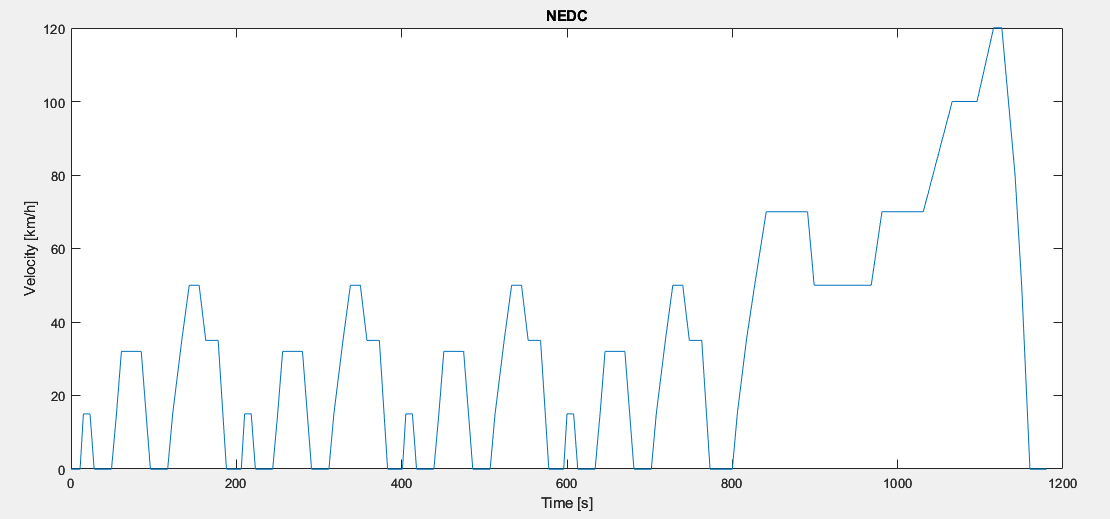

A typical WLTP (Worldwide Harmonised Light Vehicle test Procedure) cycle has 4 dynamic phases: low, middle, high , and extra high speed. The cycle time is 30 minutes and the maximum speed is 131 Km/hr.

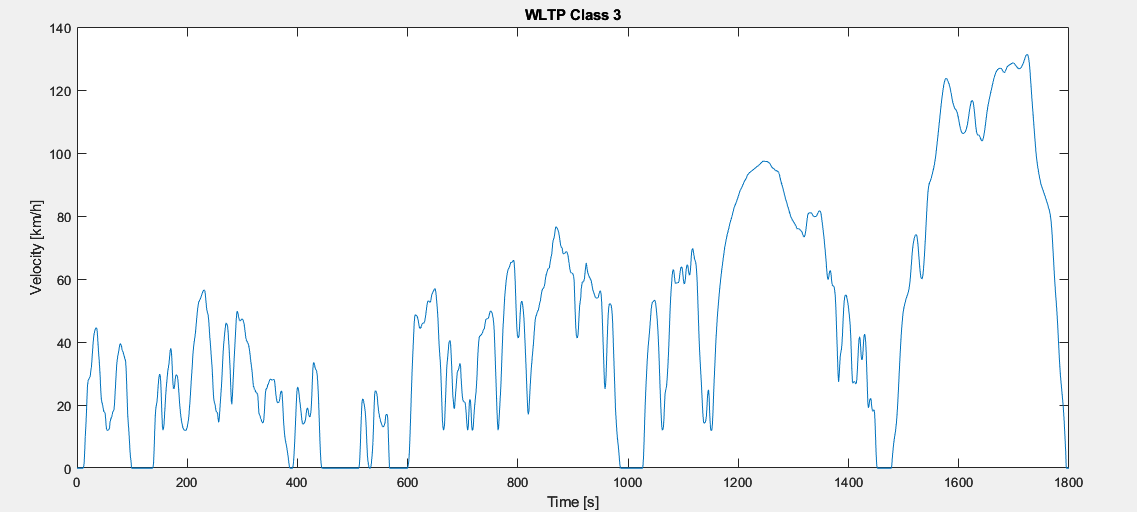

The EPA driving procedure puts the vehicle through multiple drive cycles. The two most used drive cycles are UDDS (Urban Dynamometer Driving Schedule) and HWFET (Highway Fuel Economy Driving Schedule). UUDS are for urban fuel economy and HWFET is used for highway fuel economy. 

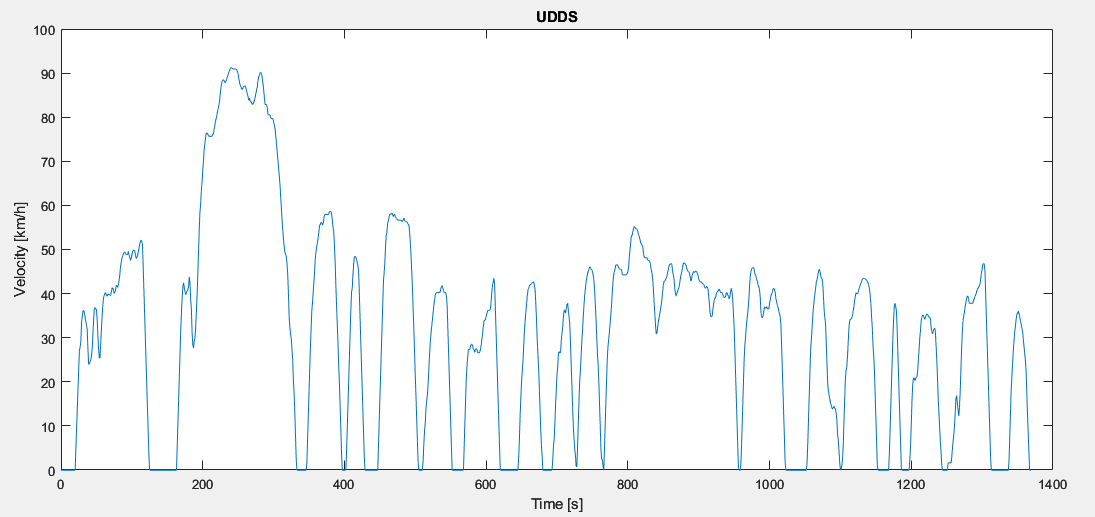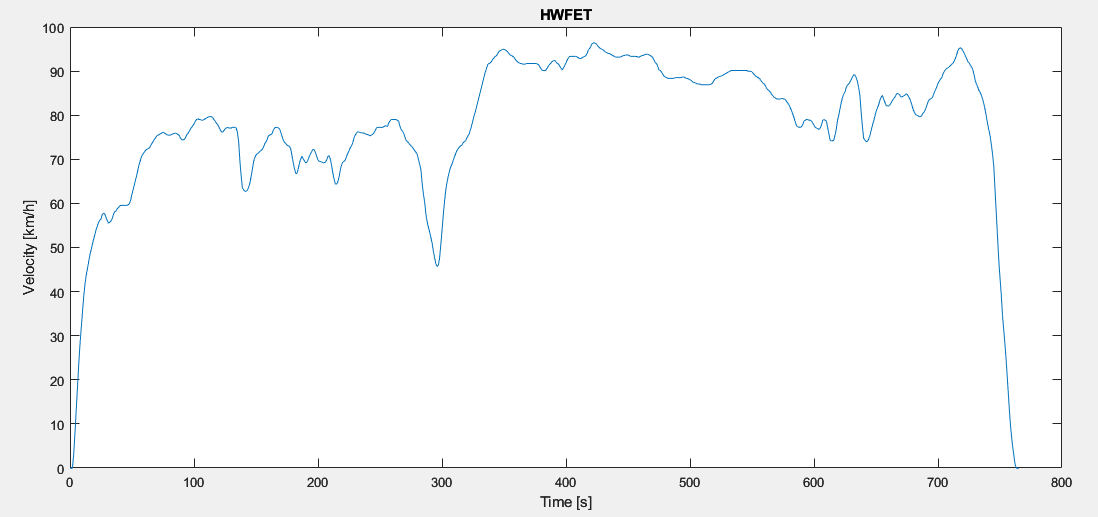

In this example, you run the NEDC and WLTC cycles with different ambient conditions and determine the range of the vehicle with a given capacity (battery size). To learn how to size a HV battery pack, see the  [Battery Pack Sizing Calculations for BEV](matlab:open('./BEVBatterySizingMain.mlx')) example.

You simulate the EPA multicycle driving procedure 98% state of charge (SoC) to 0% SoC and use energy consumed to estimate the range of the vehicle.

## Setup BEV Model

This model uses a battery electric vehicle plant model that is an electrothermal system model for the entire vehicle. The battery pack is modeled using Simscape Battery™ pack builder and has two electric motors, one in front (the main drive) and one in rear (for boost and all wheel drive modes). For more information, see [Battery Electric Vehicle](matlab:web('BatteryElectricVehicleModelOverview.html')).

To simulate the model, you must download drive profile data from [Powertrain Blockset Drive Cycle Data](https://mathworks.com/matlabcentral/fileexchange/59683-powertrain-blockset-drive-cycle-data). 

Open the BEVsystemModel model.

open_system("BEVsystemModel")
SetupPlantElectroThermal; % Setup plant for ElectroThermal configuration

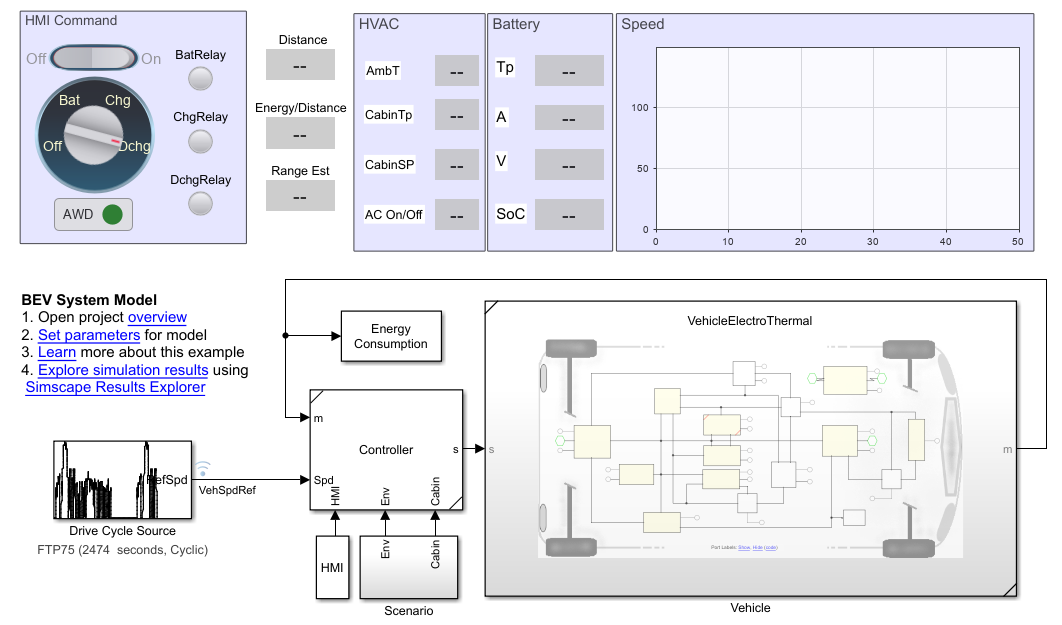

The driver control of the vehicle has an input for the vehicle speed setpoint in a Drive Cycle Source block*. *The ambient condition, cabin setpoint, and initial temperature for the battery and coolant are set through variables to simulate different scenarios.

To open torque control subsystem, navigate to **BEVsystemModel*****/Controller (Controller)/Vehicle Control/Torque Control***

## 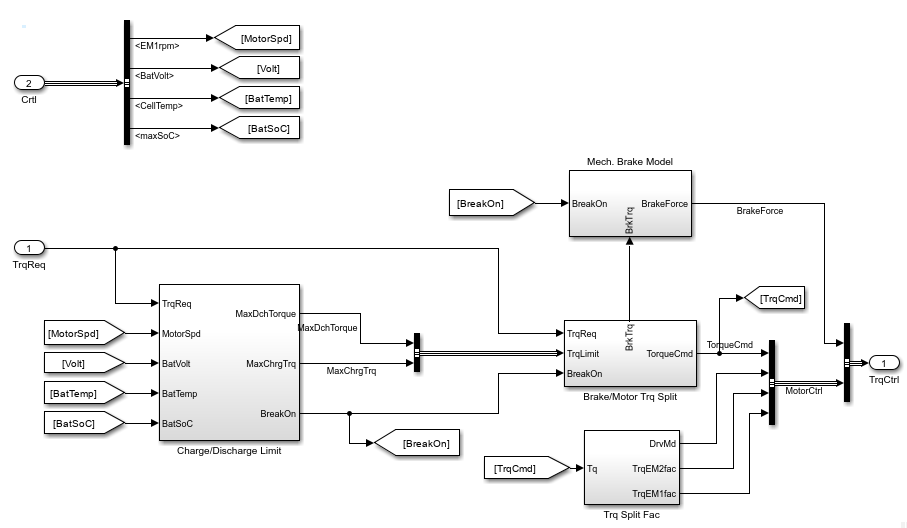

You can either manually select the drive cycle you want to run or you can set the parameters using a script. Set up the model for an NEDC drive cycle run.

driveCycle='NEDC'; % drive cycle type, choose from drive cycle source block in model
SimulationTime='1180'; % drive simulation time, put as per the drive cycle selection
speedBlock=find_system('BEVsystemModel','Name','Drive Cycle Source'); % Get the block handle
try
    set(getSimulinkBlockHandle(speedBlock),'cycleVar',driveCycle);
catch
    disp("Plese Install desired test cycle using Drive Cycle Source block in the slx model")
    disp("Running available Default cycle FTP75")
    driveCycle='FTP75';
    set(getSimulinkBlockHandle(speedBlock),'cycleVar',driveCycle);
end

Set the ambient temperature `ambient`(K), Coolant initial temperature `coolant_T_init`(K),  cabin setpoint temperature `CabinSpTp` (K), cabin initial temperature `cabin_T_init` (K), and AC on/off `AConoff`*.*

vehicleThermal.ambient=300;                % [K] Ambient temperature in
vehicleThermal.coolant_T_init=30 +273.15;  % [K] Coolant initial temperature
vehicleThermal.CabinSpTp=20 +273.15;       % [K] Cabin setpoint temperature
vehicleThermal.cabin_T_init=30 +273.15;    % [K] Cabin initial temperature
vehicleThermal.AConoff=1;                  % AC on/off variable, 0 AC off, 1 AC On

Set the battery parameters for simulation.

%% Cell Electrical
battery.T_vec=[278 293 313];                 % [K] Temperature vector T
battery.AH=34;    % Cell capacity 
battery.AH_vec=[battery.AH battery.AH battery.AH];    %[Ahr] Cell capacity vector AH(T)
battery.SOC_vec=[0, .1, .25, .5, .75, .9, 1]; % Cell state of charge vector SOC [-]
battery.initialPackSOC=0.5;	% Pack intial SOC (-)

% Run parameter file for battery
batt_BatteryManagementSystem_param;
batt_packBTMSExampleLib_param;

## Define Environmental and Operating Conditions

Environmental conditions and HVAC demands influence electric vehicle power consumption.When the vehicle runs in low temperatures, you need to heat the battery to the optimal temperature. The battery powers the HVAC system to heat the cabin. When the ambient temperature is very high the chiller needs to come in loop to cool the battery quickly. All these operations demand current from the battery and effect the range of the vehicle substantially. Since the rating of the vehicle range is done in a fixed ambient condition of 25 degC, these extra demands from the battery  result in a lower range for the car than expected.

These non-powertrain demands effect the overall range of the vehicle. The vehicle is set up to be in an equilibrium state, with an initial temperature equal to the ambient temperature. The drive cycle runs once with an initial SoC of '75%'.

**Cold ambient Condition **

The ambient temperature is set to -5 degC.

- AC On -- HVAC is on. The HVAC heating load and battery heating put a heavy demand on the battery.

- AC Off -- HVAC is off and the battery heater is the auxiliary load.

**Hot ambient condition**

The ambient temperature is set to 35 degC.

- AC On -- HVAC is on. The cabin cooling and battery chiller put a heavy demand on the battery.

- AC Off -- HVAC is off and the battery chiller is the auxiliary load.

## Run Simulations

In this example, you use precomputed results from the NEDC and WLTP profiles to demonstrate the impact of various environmental conditions on the range calculation. To change or modify the results with NEDC, run the script detailing the [NEDC profile for different ambient conditions](matlab:open('BEVrangeEstimationNEDC.m')). Similarly, to change or modify the results with WLTP, run the script detailing the [WLTP profile for different ambient conditions](matlab:open('BEVrangeEstimationWLTC.m')).

MAT files store the results for the NEDC and WLTC cycles because the runtime is considerable.

For EPA range measurement you run a multicycle simulation. The simulation starts with the ambient temperature at 25 degC and 98% SoC, multipe cycles of UDDS and HWFET until the battery is fully discharged. A MAT file stores presimulation data. To rerun the simulation refer to the M file detailing the process [EPA multicycle drive](matlab:open('BEVrangeEstimationEPA.m')).

## Plot Estimated Range of BEV

Load the results for NEDC profile runs.

load('NEDCrangeData.mat')
%Tabulated comaprison of the run
NEDC.Case     = ["NEDC Low Temp, AC ON";"NEDC Low Temp, AC OFF";"NEDC High Temp, AC ON";"NEDC High Temp, AC OFF"];
NEDC.Range    = [NEDCloTpAC.RangeRating;NEDCloTpNoAC.RangeRating;NEDChiTpAC.RangeRating;NEDChiTpNoAC.RangeRating];
NEDC.Energy   = [NEDCloTpAC.Energy;NEDCloTpNoAC.Energy;NEDChiTpAC.Energy;NEDChiTpNoAC.Energy];
NEDC.Motor1   = [NEDCloTpAC.EM1energy;NEDCloTpNoAC.EM1energy;NEDChiTpAC.EM1energy;NEDChiTpNoAC.EM1energy];
NEDC.Motor2   = [NEDCloTpAC.EM2energy;NEDCloTpNoAC.EM2energy;NEDChiTpAC.EM2energy;NEDChiTpNoAC.EM2energy];
NEDC.HVAC     = [NEDCloTpAC.HVACenergy;NEDCloTpNoAC.HVACenergy;NEDChiTpAC.HVACenergy;NEDChiTpNoAC.HVACenergy];
NEDC.Aux      = [NEDCloTpAC.AuxEnergy; NEDCloTpNoAC.AuxEnergy; NEDChiTpAC.AuxEnergy; NEDChiTpNoAC.AuxEnergy];
rangeDataNEDC = array2table([NEDC.Range,NEDC.Energy,NEDC.Motor1,NEDC.Motor2,NEDC.HVAC,NEDC.Aux],...
           'VariableNames',{'Range (kms)','Energy (Whr)','Motor1 Losses (Whr)','Motor2 Losses (Whr)','HVAC Losses (Whr)','Aux. Losses (Whr)'})


%% plot NEDC range and energy consumptiom
Case = categorical({'Low\newlineTemp\newlineAC ON';'Low\newlineTemp\newlineAC OFF';'High\newlineTemp\newlineAC ON';'High\newlineTemp\newlineAC OFF'});
Case = reordercats(Case,{'Low\newlineTemp\newlineAC ON';'Low\newlineTemp\newlineAC OFF';'High\newlineTemp\newlineAC ON';'High\newlineTemp\newlineAC OFF'});

Energy_NEDC=[NEDC.Motor1(1);NEDC.Motor2(1);NEDC.HVAC(1);NEDC.Aux(1)];
for i=2:4
 Energy_NEDC=[Energy_NEDC [NEDC.Motor1(i);NEDC.Motor2(i);NEDC.HVAC(i);NEDC.Aux(i)]];
end

figure
% yyaxis left
b_NEDC = bar(Case,Energy_NEDC','stacked');
ylim([0 2500])
yyaxis right
p_NEDC = plot(Case,NEDC.Range);
ylim([0 400])

title('NEDC Range Plot')
yyaxis left
ylabel('Energy (Whr)')
yyaxis right
ylabel('Range (km)')
p_NEDC.LineWidth = 3;

% Legend
set(b_NEDC, {'DisplayName'}, {'Motor 1','Motor 2','HVAC','Aux'}')
set(p_NEDC, {'DisplayName'}, {'Range'}')
legend('Location', 'Northeastoutside') 

**WLTC drive**

Load the results for WLTC profile runs.

load('WLTCrangeData.mat')
%Tabulated comaprison of the run
WLTC.Case     = ["WLTC Low Temp, AC";"WLTC Low Temp, No AC";"WLTC High Temp, AC";"WLTC High Temp, No AC"];
WLTC.Range    = [WLTCloTpAC.RangeRating;WLTCloTpNoAC.RangeRating;WLTChiTpAC.RangeRating;WLTChiTpNoAC.RangeRating];
WLTC.Energy   = [WLTCloTpAC.Energy;WLTCloTpNoAC.Energy;WLTChiTpAC.Energy;WLTChiTpNoAC.Energy];
WLTC.Motor1   = [WLTCloTpAC.EM1energy;WLTCloTpNoAC.EM1energy;WLTChiTpAC.EM1energy;WLTChiTpNoAC.EM1energy];
WLTC.Motor2   = [WLTCloTpAC.EM2energy;WLTCloTpNoAC.EM2energy;WLTChiTpAC.EM2energy;WLTChiTpNoAC.EM2energy];
WLTC.HVAC     = [WLTCloTpAC.HVACenergy;WLTCloTpNoAC.HVACenergy;WLTChiTpAC.HVACenergy;WLTChiTpNoAC.HVACenergy];
WLTC.Aux      = [WLTCloTpAC.AuxEnergy; WLTCloTpNoAC.AuxEnergy; WLTChiTpAC.AuxEnergy; WLTChiTpNoAC.AuxEnergy];
rangeDataWLTC = array2table([WLTC.Range,WLTC.Energy,WLTC.Motor1,WLTC.Motor2,WLTC.HVAC,WLTC.Aux],...
           'VariableNames',{'Range (kms)','Energy (Whr)','Motor1 Losses (Whr)','Motor2 Losses (Whr)','HVAC Losses (Whr)','Aux. Losses (Whr)'})

%% plot WLTC range and energy consumptiom
Case = categorical({'Low\newlineTemp\newlineAC ON';'Low\newlineTemp\newlineAC OFF';'High\newlineTemp\newlineAC ON';'High\newlineTemp\newlineAC OFF'});
Case = reordercats(Case,{'Low\newlineTemp\newlineAC ON';'Low\newlineTemp\newlineAC OFF';'High\newlineTemp\newlineAC ON';'High\newlineTemp\newlineAC OFF'});

Energy_WLTC=[WLTC.Motor1(1);WLTC.Motor2(1);WLTC.HVAC(1);WLTC.Aux(1)];
for i=2:4
 Energy_WLTC=[Energy_WLTC [WLTC.Motor1(i);WLTC.Motor2(i);WLTC.HVAC(i);WLTC.Aux(i)]];
end

figure
% yyaxis left
b_WLTC = bar(Case,Energy_WLTC','stacked','DisplayName','1');
ylim([0 5000])
yyaxis right
p_WLTC = plot(Case,WLTC.Range);
ylim([0 300])

title('WLTC Range Plot')
yyaxis left
ylabel('Energy (Whr)')
yyaxis right
ylabel('Range (km)')
p_WLTC.LineWidth = 3;
% Legend
set(b_WLTC, {'DisplayName'}, {'Motor 1','Motor 2','HVAC','Aux'}')
set(p_WLTC, {'DisplayName'}, {'Range'}')
legend('Location', 'Northeastoutside') 

## Useful Links

[Electric Vehicle Design with Simscape](matlab:web('electricvehicledesignoverview.html'))

[NEDC profile for different ambient conditions](matlab:open('BEVrangeEstimationNEDC.m'))

[WLTP profile for different ambient conditions](matlab:open('BEVrangeEstimationWLTC.m'))